Función que obtiene la cinemática directa del cuadrúpedo, ya sea de sus patas traseras (2 DOF) o de sus patas delanteras (3 DOF). Para las patas traseras se utiliza geometría para obtener la cinemática directa, mientras que para las delanteras se emplea una matriz de Denavit-Hartenberg. 

Uso: `T = cuadFK(q, DOF, IT_B, ET_F)`

- *q* = Configuración del robot

- *DOF* = Número de grados de libertad. Opciones = 2 o 3

- *IT_B* = Transformación de base

- *ET_F* = Transformación de efector final

- *T *= Transformación homogénea del espacio de configuración al de tarea

2 DOF

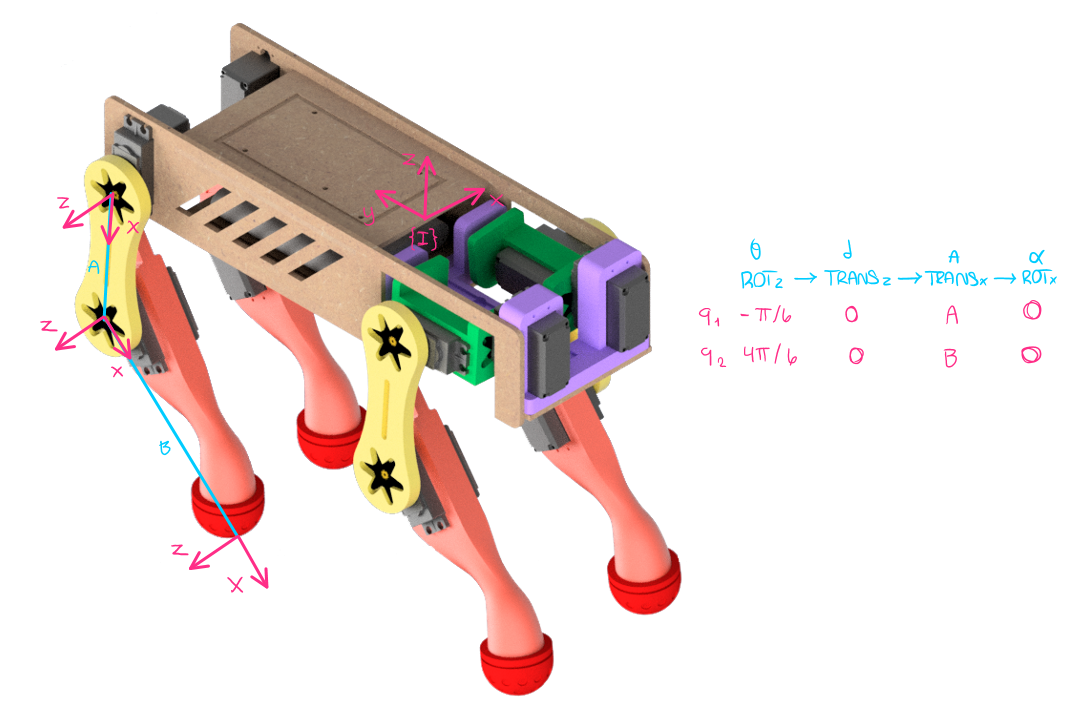

3 DOF

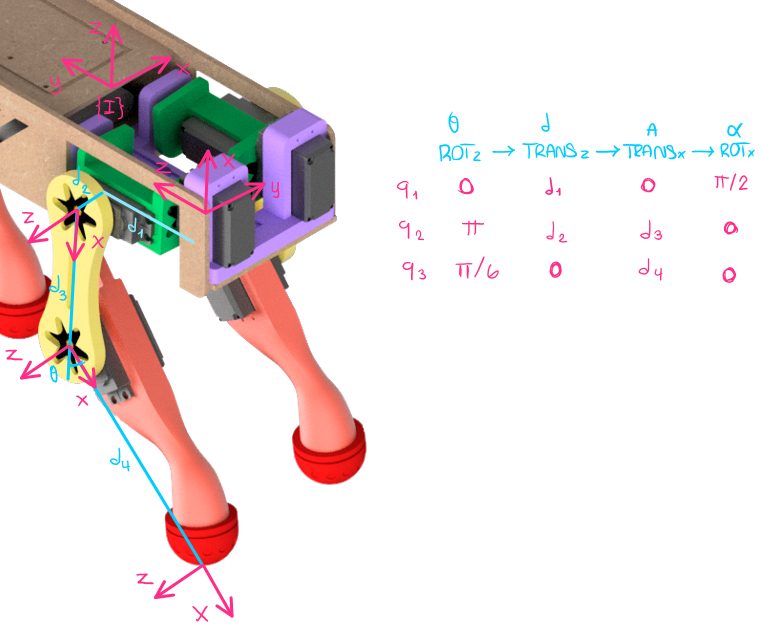

function T = cuadFK(q, DOF, IT_B, ET_F)

switch DOF   
    % Cinemática directa para pata de 3 DOF
    case 3
        % Dimensiones de pata
        d1 = 5/100;
        d2 = 1.5/100;
        d3 = 8/100;
        d4 = 129/1000;
        
        % Matriz de Denavit-Hartenberg para patas de 3 grados de libertad.
        % Posición 0: Sentado
        DH = [             q(1), d1,  0, pi/2; 
               q(2) + pi - pi/6, d2, d3,    0; 
                  q(3) + 4*pi/6,  0, d4,    0];
              
    case 2
        
        % Forma analítica: No se pudo implementar correctamente
        % Posicion = [A*cos(q(1)) - B*cos(q(2));
        %             A*sin(q(1)) + B*sin(q(2));
        %             0];
        % Psi = q(1) + q(2);   
        %
        % Orientacion = [cos(Psi) -sin(Psi) 0;
        %                sin(Psi)  cos(Psi) 0;
        %                       0         0 1];
        
        % Dimensiones de pata
        A = 80 / 1000;
        B = 129 / 1000;
        
        % Matriz de Denavit-Hartenberg para patas de 2 grados de libertad.
        % Posición 0: Sentado
        DH = [   q(1) - pi/6, 0, A, 0; 
               q(2) + 4*pi/6, 0, B, 0];
              
end

% Se obtiene la cinemática directa a partir de la matriz de Denavit-Hartenberg 
FK = eye(4);
for i = 1:size(DH, 1)
    % Se extraen los valores de "theta", "d", "a" y "alpha" de la fila
    % actual (i) de la matriz de Denavit-Hartenberg.
    theta = DH(i,1);
    d = DH(i,2);
    a = DH(i,3);
    alpha = DH(i,4);

    % Los ángulos y distancias se convierten en matrices de rotación y
    % traslación homogéneas.
    Rz = [cos(theta),-sin(theta),0,0; sin(theta),cos(theta),0,0; 0,0,1,0; 0,0,0,1];
    Tz = [1,0,0,0; 0,1,0,0; 0,0,1,d; 0,0,0,1];
    Tx = [1,0,0,a; 0,1,0,0; 0,0,1,0; 0,0,0,1];
    Rx = [1,0,0,0; 0,cos(alpha),-sin(alpha),0; 0,sin(alpha),cos(alpha),0; 0,0,0,1];
    A = Rz*Tz*Tx*Rx;

    % Se "acumula" el efecto de las transformaciones de cada fila de la
    % matriz de Denavit-Hartenberg
    FK = FK * A;
    
    % Transformaciones de Base y Herramienta
    %  - IT_B: Transformación de base que mueve la pata del marco inercial
    %    del robot total al inicio del robot.
    %  - ET_F: Transformación de herramienta que desplaza el marco de
    %    referencia de la punta de la pata a la punta de la herramienta
    %    o efector final acoplado            
    T = IT_B * FK * ET_F;

end

end